# Image segmentation using k-means

Let's set the standard matlab colors as cluster colorings. We have at most $6$ meaningfull clusters, however we insert an additional color for good meassure.

cmap =[ [0 0.4470 0.7410]	;...
[0.8500 0.3250 0.0980]	;...
[0.9290 0.6940 0.1250]	;...
[0.4940 0.1840 0.5560]	;...
[0.4660 0.6740 0.1880]	;...
[0.3010 0.7450 0.9330]	;...
[0.6350 0.0780 0.1840]
    ]

cmap =          0    0.4470    0.7410
    0.8500    0.3250    0.0980
    0.9290    0.6940    0.1250
    0.4940    0.1840    0.5560
    0.4660    0.6740    0.1880
    0.3010    0.7450    0.9330
    0.6350    0.0780    0.1840


## PMF logo

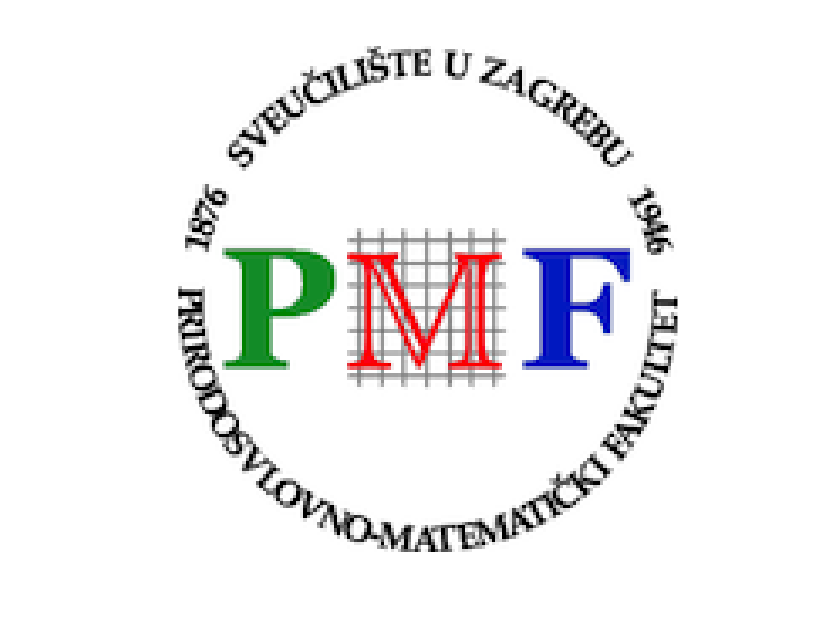

I_1=imread("pmf.png");
imshow(I_1); 

[h_1,w_1,~]=size(I_1);

We are attempting to segment each part of the picture.

### Iterative k-means using RGB colorspace 

#### 
$$k=2$$


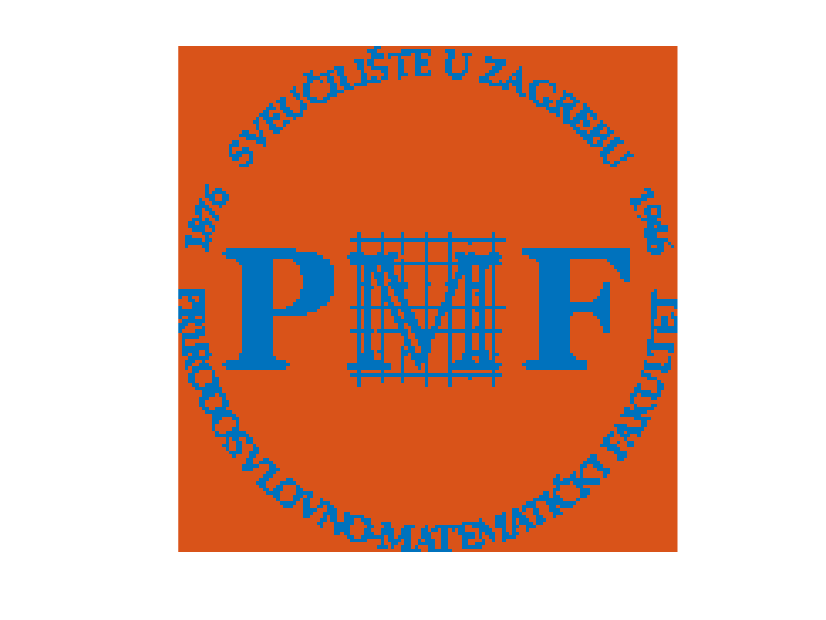

P_pmf_2=iterative_k_means(reshape(double(I_1),h_1*w_1,3),2);
imshow(reshape(cmap(reshape(P_pmf_2,[h_1,w_1]), :), h_1, w_1, 3));

#### 
$$k=3$$


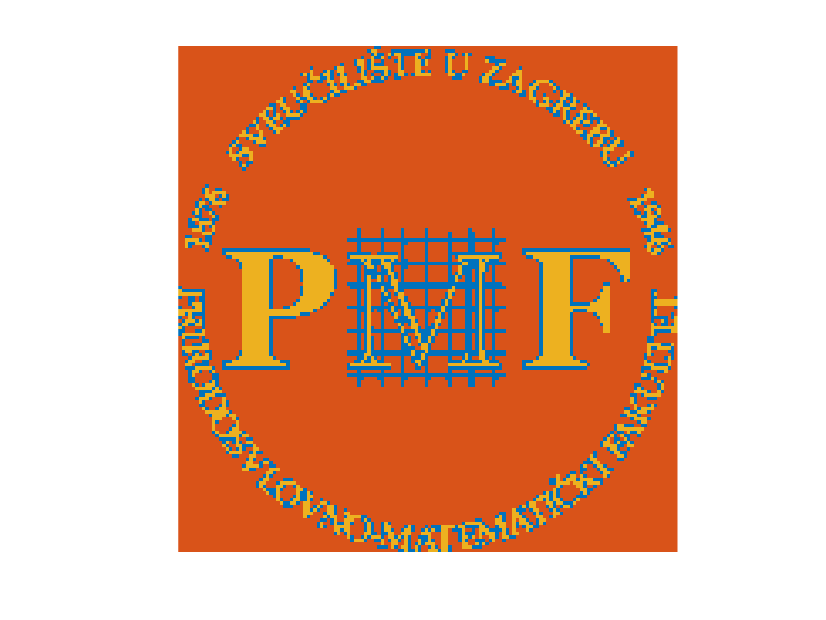

P_pmf_3=iterative_k_means(reshape(double(I_1),h_1*w_1,3),3);
imshow(reshape(cmap(reshape(P_pmf_3,[h_1,w_1]), :), h_1, w_1, 3));

#### 
$$k=4$$


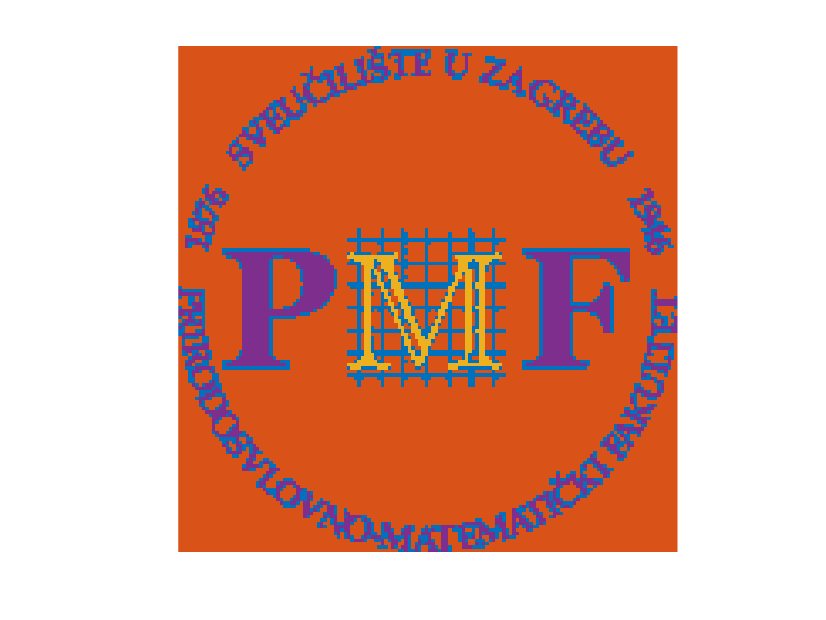

P_pmf_4=iterative_k_means(reshape(double(I_1),h_1*w_1,3),4);
imshow(reshape(cmap(reshape(P_pmf_4,[h_1,w_1]), :), h_1, w_1, 3));

#### 
$$k=5$$


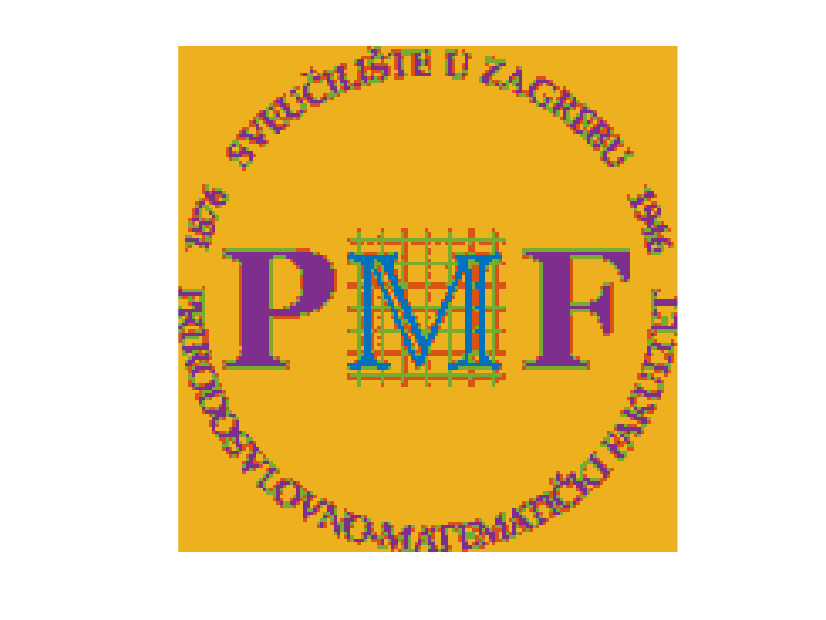

P_pmf_5=iterative_k_means(reshape(double(I_1),h_1*w_1,3),5);
imshow(reshape(cmap(reshape(P_pmf_5,[h_1,w_1]), :), h_1, w_1, 3));

#### 
$$k=6$$


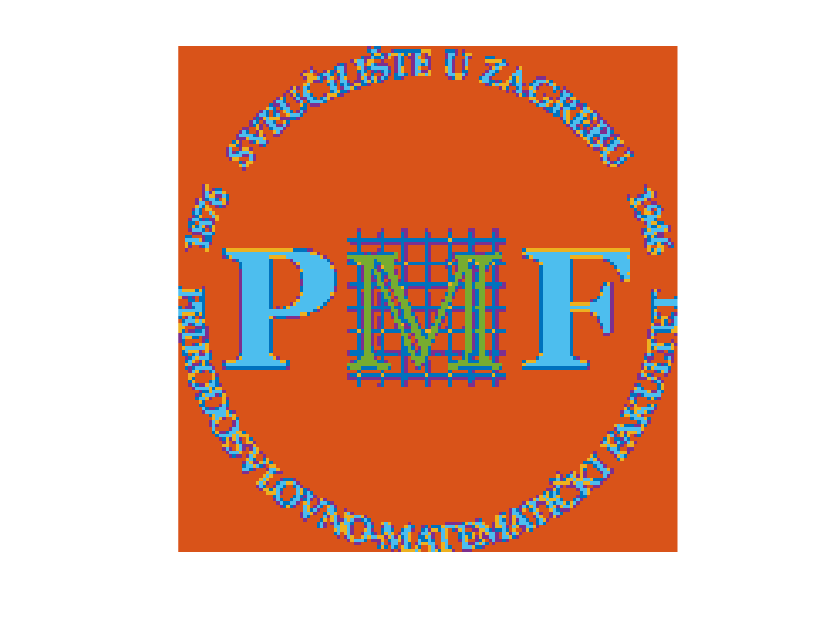

P_pmf_6=iterative_k_means(reshape(double(I_1),h_1*w_1,3),6);
imshow(reshape(cmap(reshape(P_pmf_6,[h_1,w_1]), :), h_1, w_1, 3));

### Conclusion

We cannot seem to separate letters 'P' and 'F' which are green and blue color. Perhaps a different colorspace would do the trick.

### Iterative k-means using oklab colorspace 

#### 
$$k=2$$


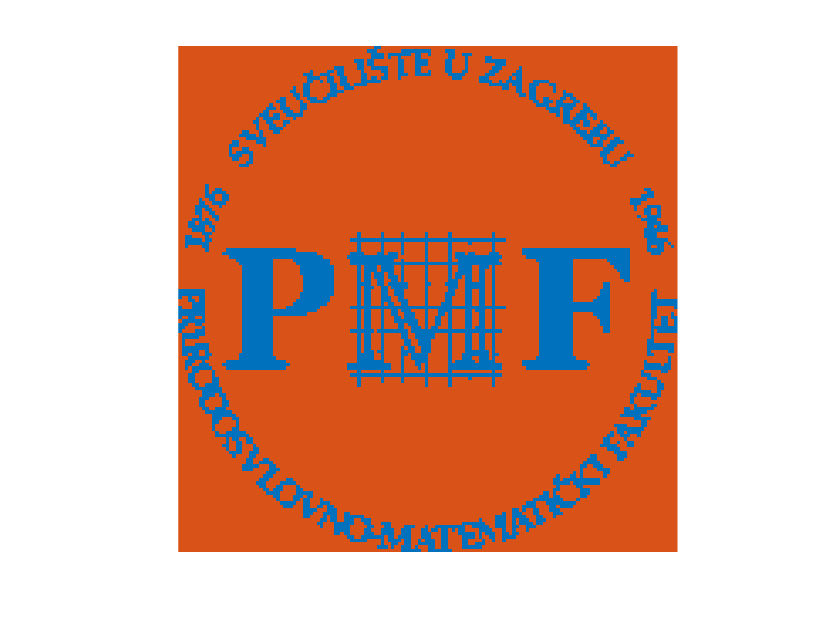

P_pmf_2_ok=iterative_k_means( ...
    reshape(rgb2oklab(double(I_1)),h_1*w_1,3),2);
imshow(reshape(cmap(reshape(P_pmf_2_ok,[h_1,w_1]), :), h_1, w_1, 3));

#### 
$$k=3$$


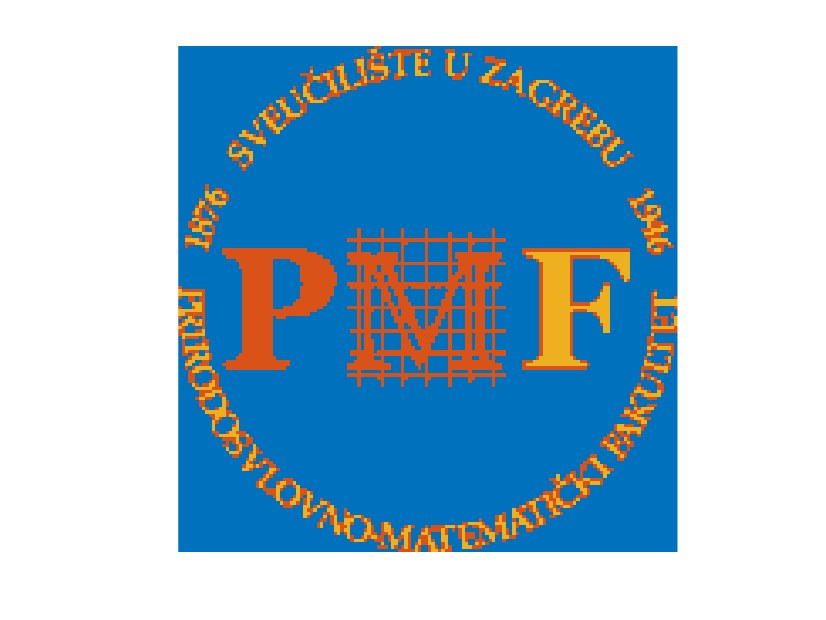

P_pmf_3_ok=iterative_k_means( ...
    reshape(rgb2oklab(double(I_1)),h_1*w_1,3),3);
imshow(reshape(cmap(reshape(P_pmf_3_ok,[h_1,w_1]), :), h_1, w_1, 3));

#### 
$$k=4$$


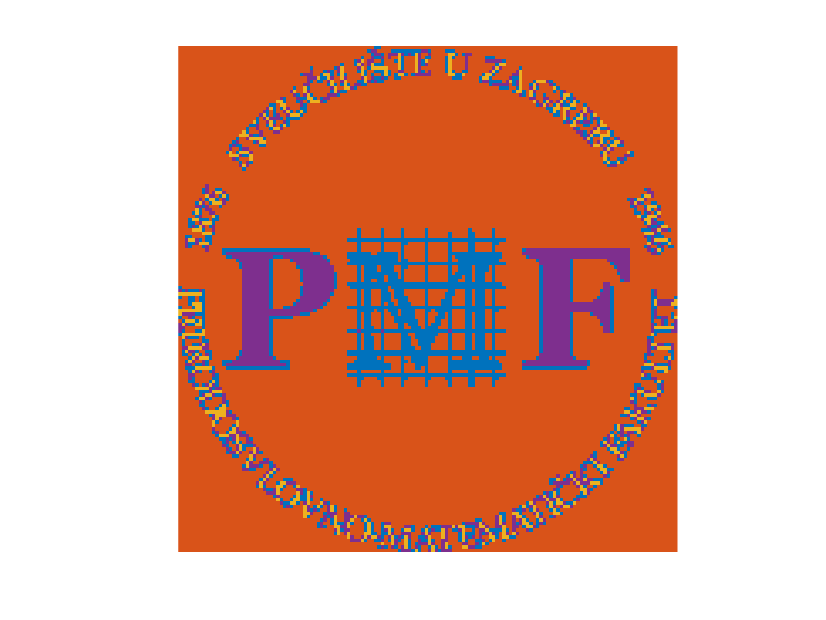

P_pmf_4_ok=iterative_k_means( ...
    reshape(rgb2oklab(double(I_1)),h_1*w_1,3),4);
imshow(reshape(cmap(reshape(P_pmf_4_ok,[h_1,w_1]), :), h_1, w_1, 3));

#### 
$$k=5$$


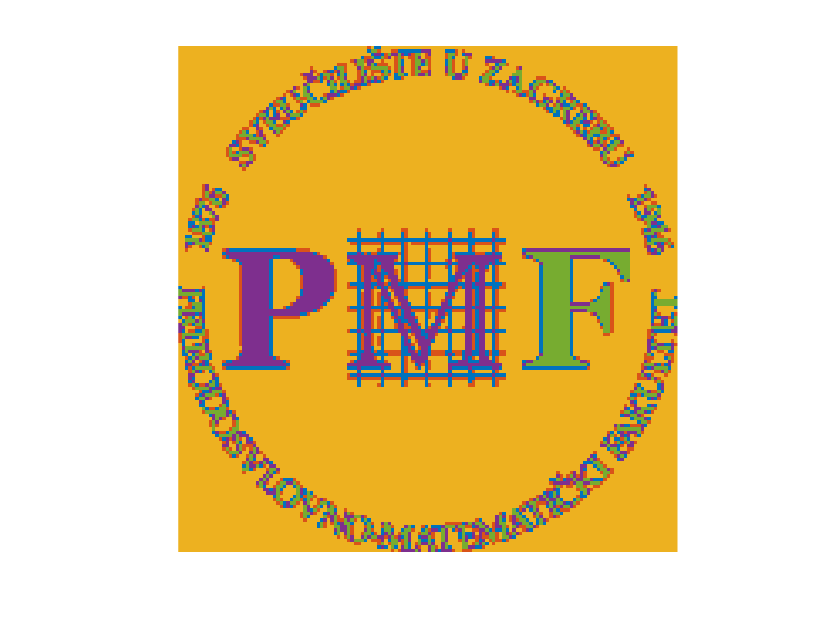

P_pmf_5_ok=iterative_k_means( ...
    reshape(rgb2oklab(double(I_1)),h_1*w_1,3),5);
imshow(reshape(cmap(reshape(P_pmf_5_ok,[h_1,w_1]), :), h_1, w_1, 3));

#### 
$$k=6$$


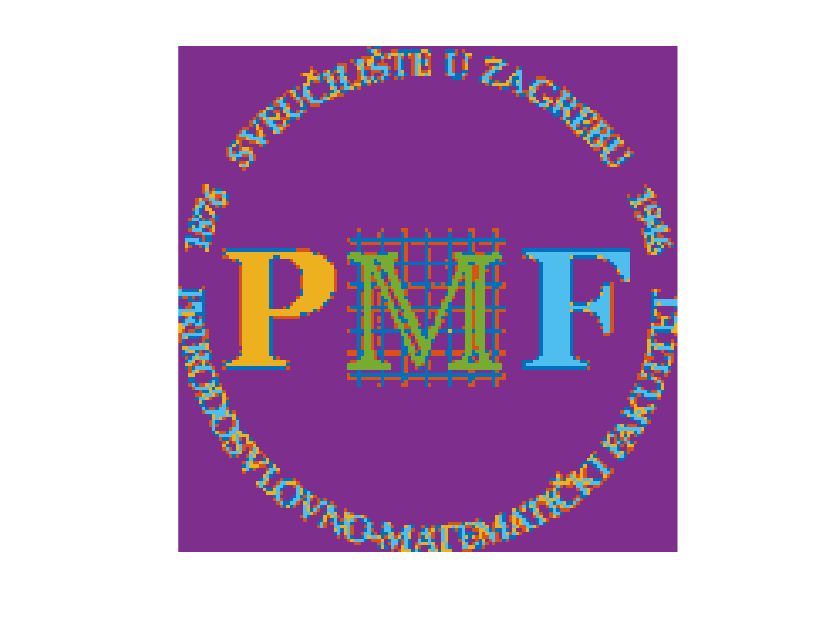

P_pmf_6_ok=iterative_k_means( ...
    reshape(rgb2oklab(double(I_1)),h_1*w_1,3),6);
imshow(reshape(cmap(reshape(P_pmf_6_ok,[h_1,w_1]), :), h_1, w_1, 3));

### Conclusion

For $k=6$ some good separation of the letters 'P', 'M' and 'F' occured, but the outter ones are in multiple colors. Perhaps a different clustering algorithm would do the trick, but oklab colorspace seems to work better than the regular RGB, so we will use the former one.

## Olympic rings

We choose olympic rings for their color complex, but it will also pose an interesting challenge in settin the correct parameters when taking a kernel approach.

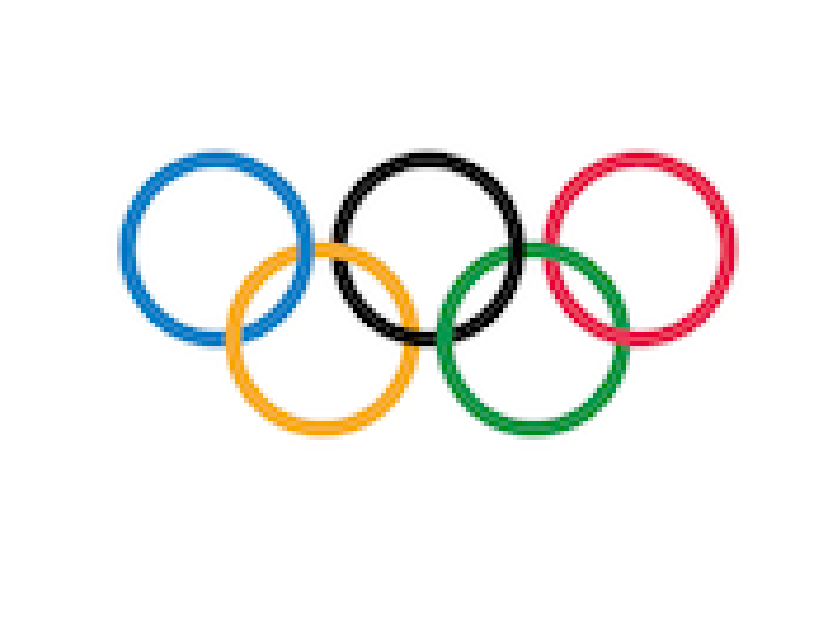

I_2=imread("olympia.png");
imshow(I_2);

[h_2,w_2,~]=size(I_2);

### Iterative k-means using oklab colorspace 

#### 
$$k=2$$


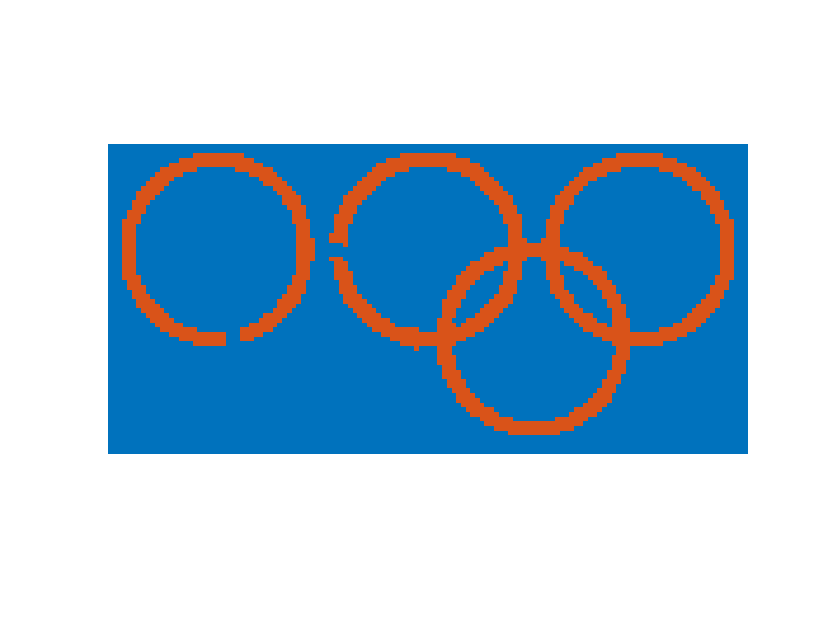

P_olympia_2_ok=iterative_k_means( ...
    reshape(rgb2oklab(double(I_2)),h_2*w_2,3),2);
imshow(reshape(cmap(reshape(P_olympia_2_ok,[h_2,w_2]), :), h_2, w_2, 3));

#### 
$$k=3$$


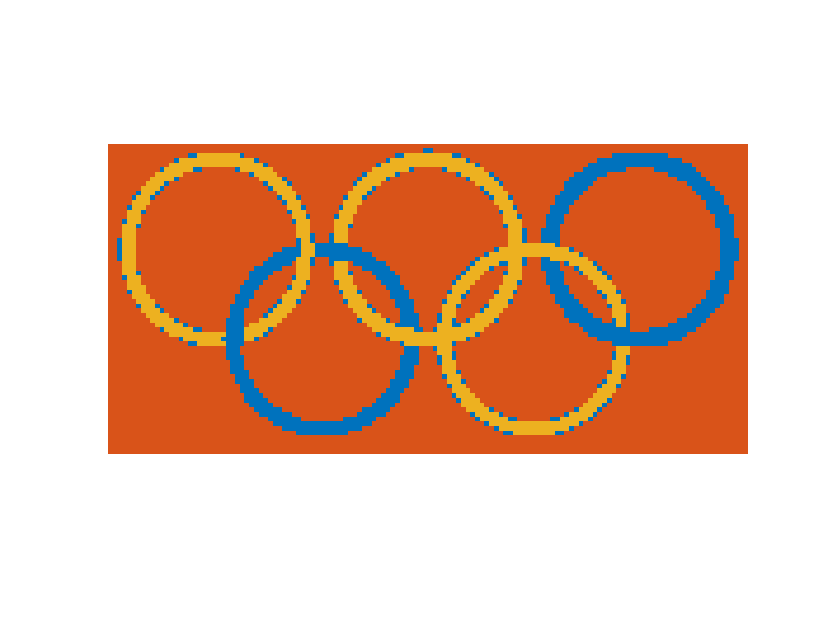

P_olympia_3_ok=iterative_k_means( ...
    reshape(rgb2oklab(double(I_2)),h_2*w_2,3),3);
imshow(reshape(cmap(reshape(P_olympia_3_ok,[h_2,w_2]), :), h_2, w_2, 3));

#### 
$$k=4$$


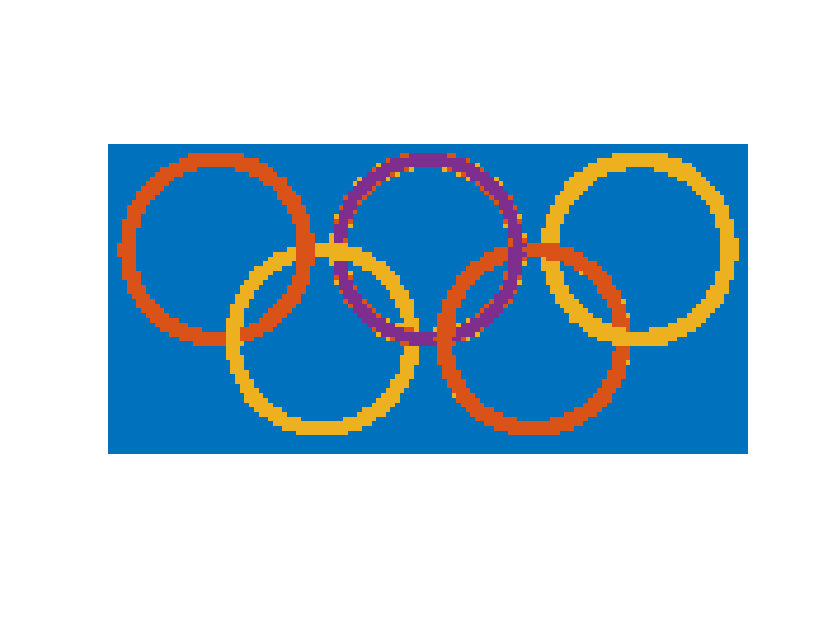

P_olympia_4_ok=iterative_k_means( ...
    reshape(rgb2oklab(double(I_2)),h_2*w_2,3),4);
imshow(reshape(cmap(reshape(P_olympia_4_ok,[h_2,w_2]), :), h_2, w_2, 3));

#### 
$$k=5$$


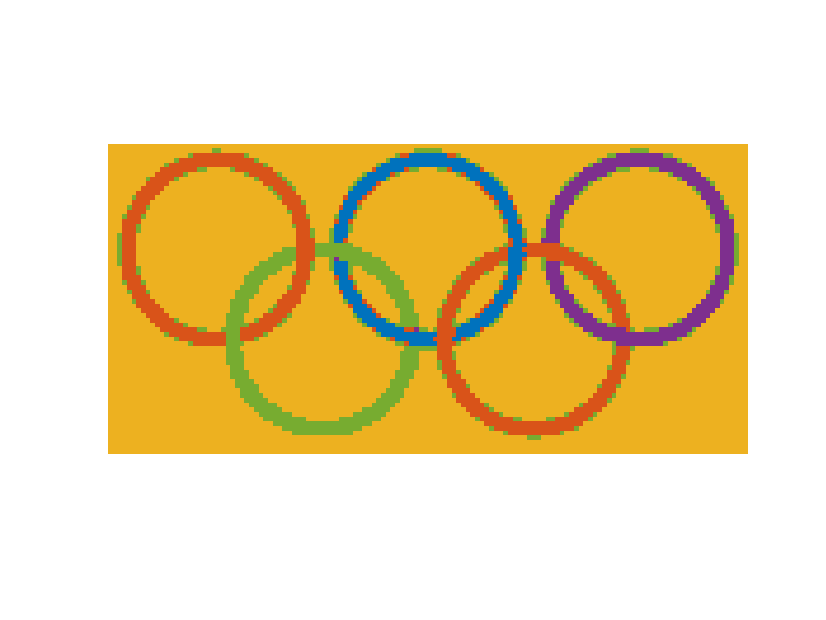

P_olympia_5_ok=iterative_k_means( ...
    reshape(rgb2oklab(double(I_2)),h_2*w_2,3),5);
imshow(reshape(cmap(reshape(P_olympia_5_ok,[h_2,w_2]), :), h_2, w_2, 3));

#### 
$$k=6$$


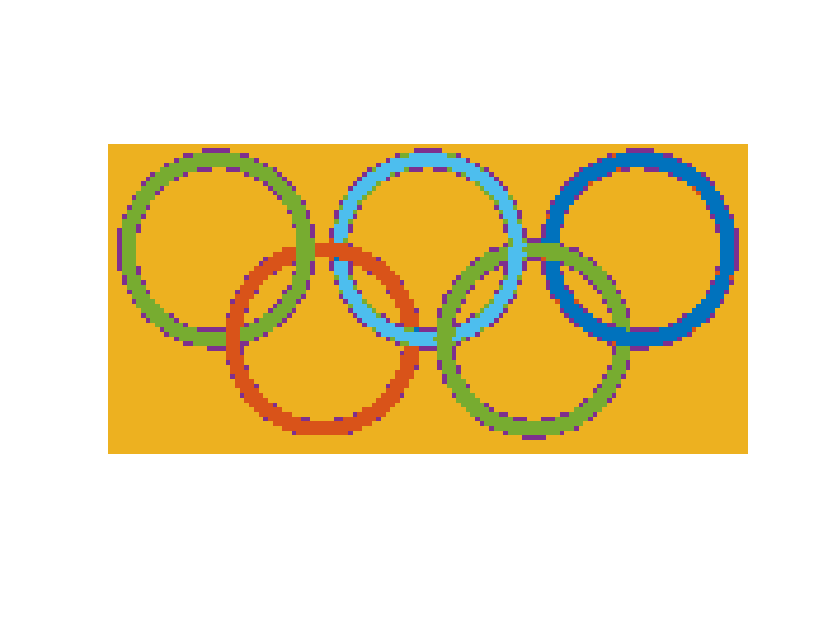

P_olympia_6_ok=iterative_k_means( ...
    reshape(rgb2oklab(double(I_2)),h_2*w_2,3),6);
imshow(reshape(cmap(reshape(P_olympia_6_ok,[h_2,w_2]), :), h_2, w_2, 3));

#### 
$$k=7$$


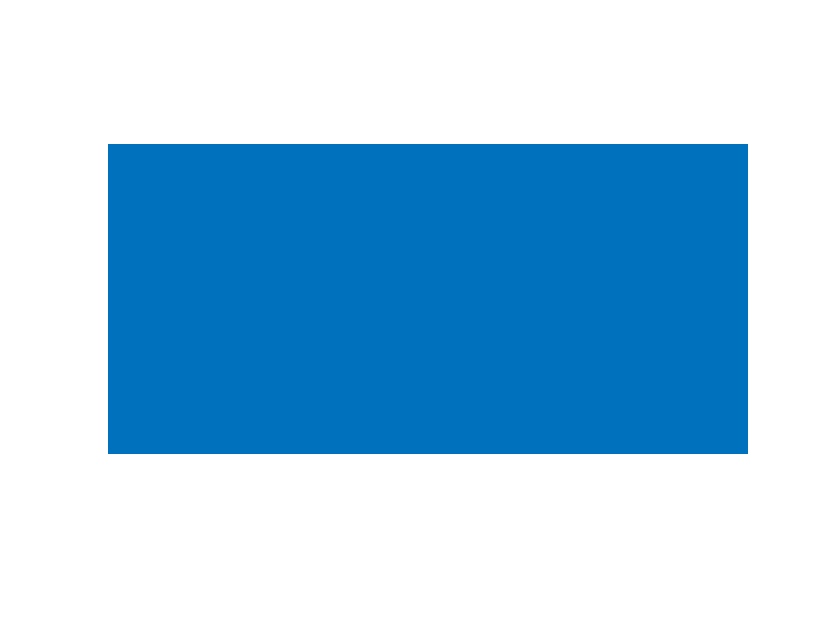

P_olympia_7_ok=iterative_k_means( ...
    reshape(rgb2oklab(double(I_2)),h_2*w_2,3),7);
imshow(reshape(cmap(reshape(P_olympia_7_ok,[h_2,w_2]), :), h_2, w_2, 3));

### Conclusion

Olympic rings seem to have the same problem with separating green and blue colors. It is interesting why can't we separate the yellow ring from the white background. Let's try to use RGB colorspace again.

### Iterative k-means using RGB colorspace 

#### 
$$k=2$$


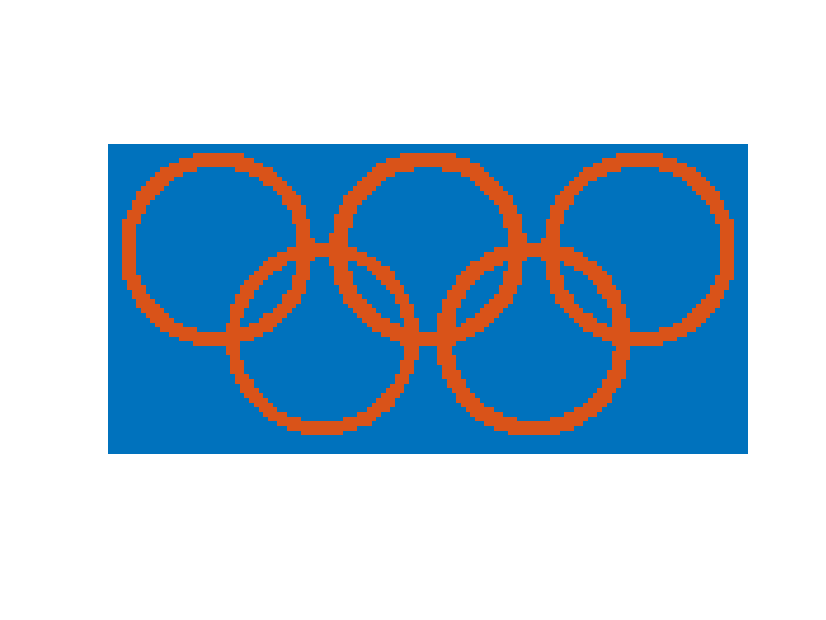

P_olympia_2=iterative_k_means( ...
    reshape((double(I_2)),h_2*w_2,3),2);
imshow(reshape(cmap(reshape(P_olympia_2,[h_2,w_2]), :), h_2, w_2, 3));

#### 
$$k=3$$


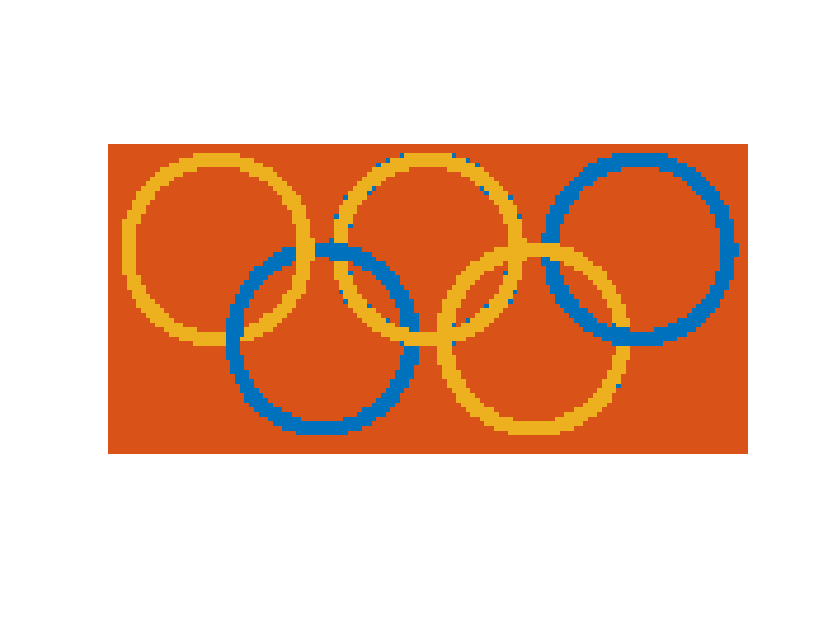

P_olympia_3=iterative_k_means( ...
    reshape((double(I_2)),h_2*w_2,3),3);
imshow(reshape(cmap(reshape(P_olympia_3,[h_2,w_2]), :), h_2, w_2, 3));

#### 
$$k=4$$


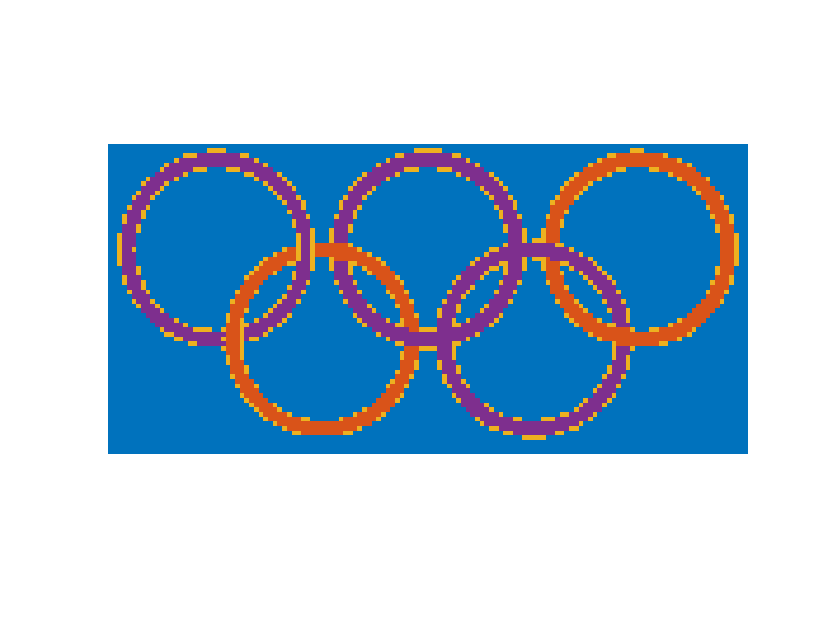

P_olympia_4=iterative_k_means( ...
    reshape((double(I_2)),h_2*w_2,3),4);
imshow(reshape(cmap(reshape(P_olympia_4,[h_2,w_2]), :), h_2, w_2, 3));

#### 
$$k=5$$


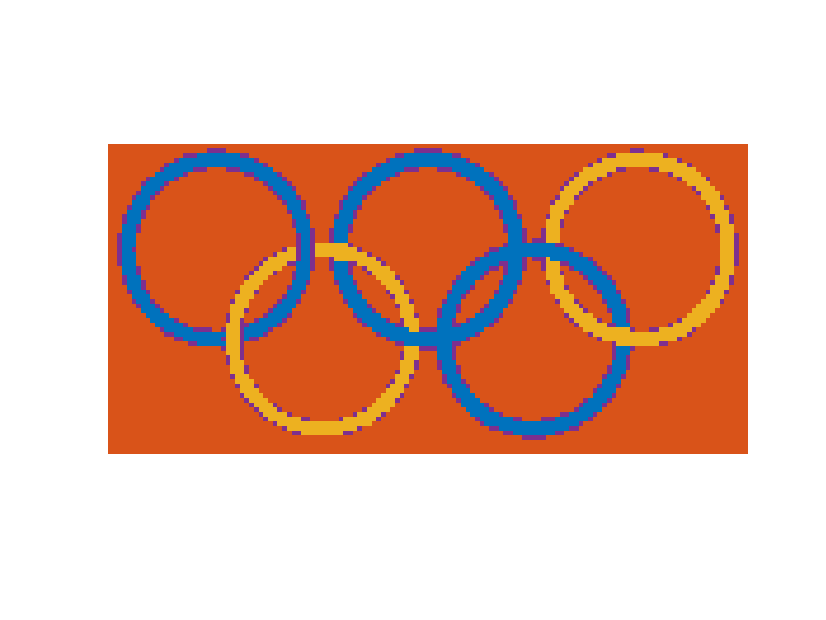

P_olympia_5=iterative_k_means( ...
    reshape((double(I_2)),h_2*w_2,3),5);
imshow(reshape(cmap(reshape(P_olympia_5,[h_2,w_2]), :), h_2, w_2, 3));

#### 
$$k=6$$


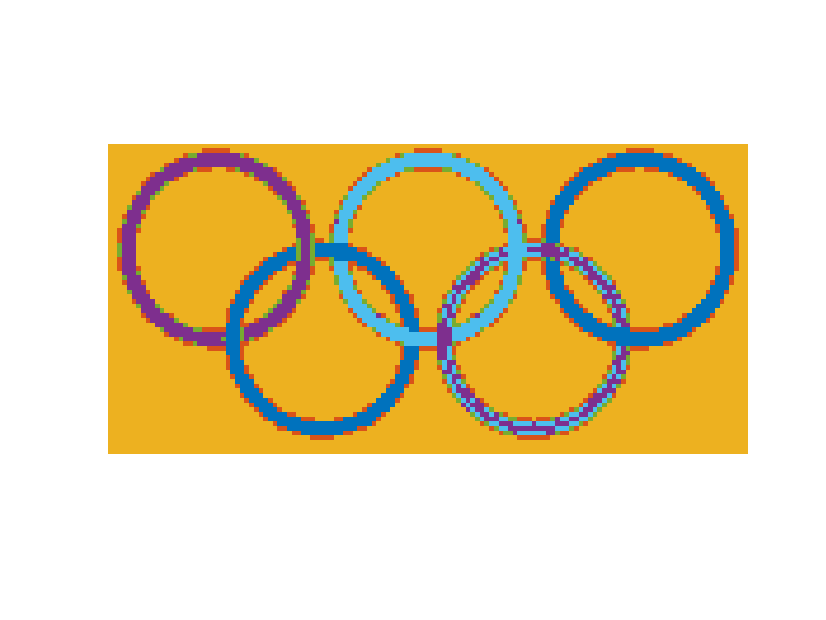

P_olympia_6=iterative_k_means( ...
    reshape((double(I_2)),h_2*w_2,3),6);
imshow(reshape(cmap(reshape(P_olympia_6,[h_2,w_2]), :), h_2, w_2, 3));

#### 
$$k=7$$


P_olympia_7=iterative_k_means( ...
    reshape((double(I_2)),h_2*w_2,3),7);
imshow(reshape(cmap(reshape(P_olympia_7,[h_2,w_2]), :), h_2, w_2, 3));

### Conclusion

We were right in the first place, oklab colorspace is the better option. It does not however separate the background correctly, unline the RGB colorspace, but this will change using spectral clustering.

# Image segmentation using spectral clustering

Here are some succesfull results. For time menagement load the 'image_seg.mat' data and comment out the function.

## PMF logo

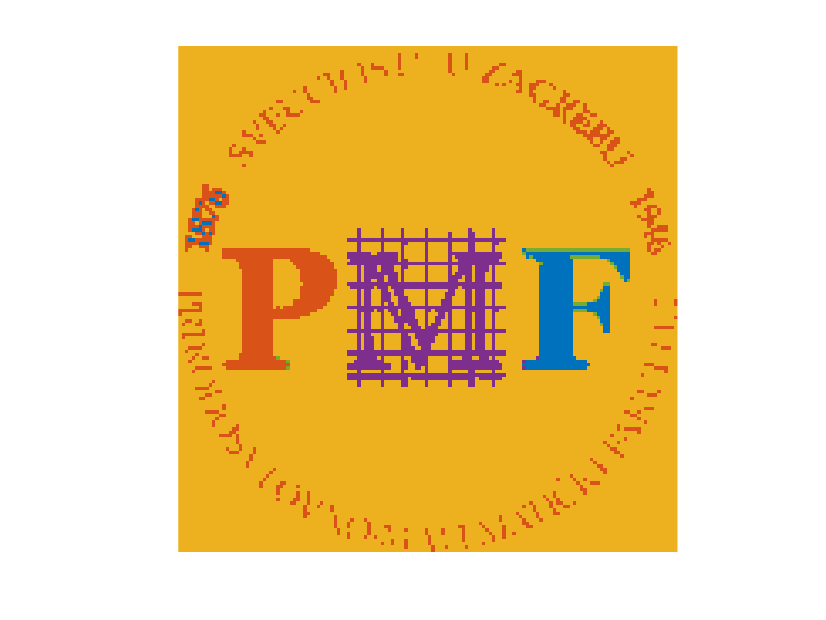

P_pmf_7=normalized_cuts(gaussian_img(I_1,0,10,2),5);
imshow(reshape(cmap(reshape(P_pmf_7,[h_1,w_1]), :), h_1, w_1, 3));

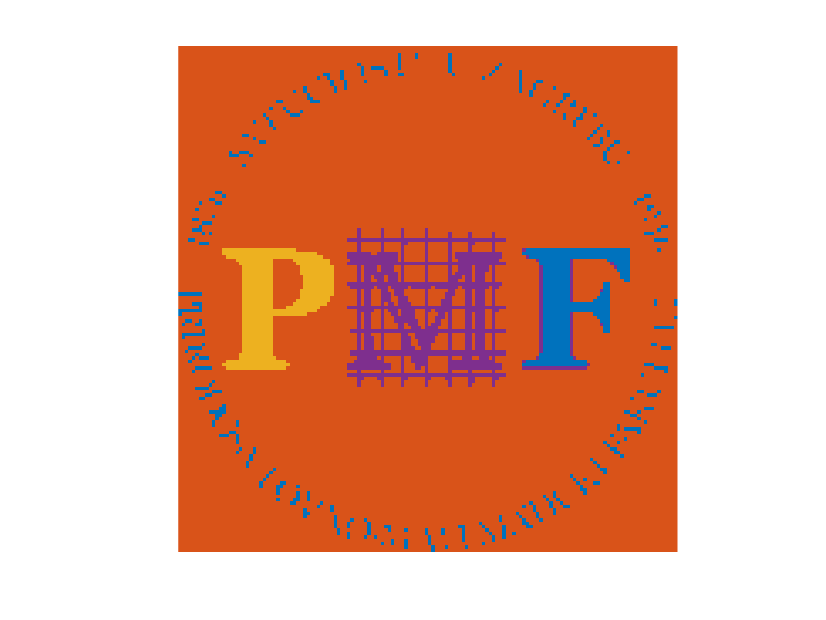

P_pmf_8=normalized_cuts(gaussian_img(I_1,0,15,2),5);
imshow(reshape(cmap(reshape(P_pmf_8,[h_1,w_1]), :), h_1, w_1, 3));

## Olympic rings

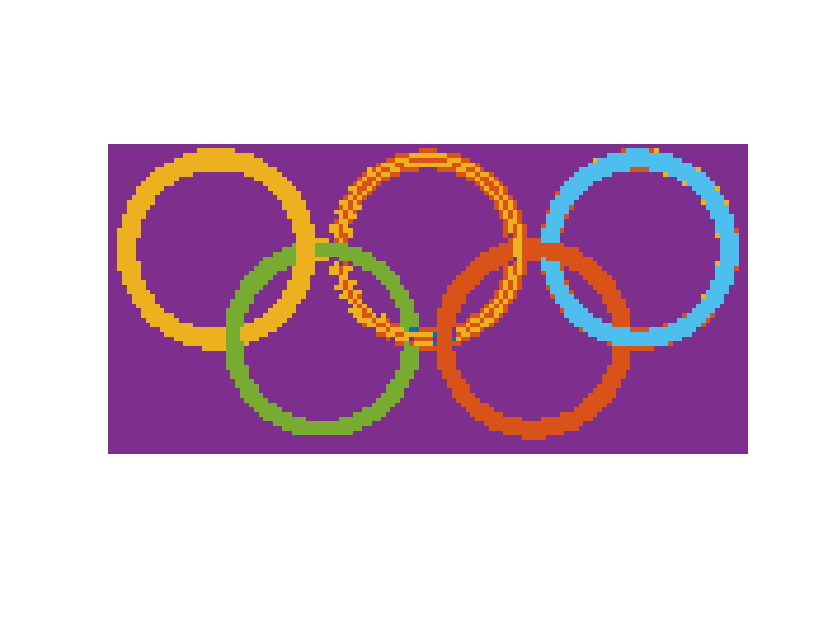

P_olympia=normalized_cuts(gaussian_img(I_2,5,10,2),6);
imshow(reshape(cmap(reshape(P_olympia,h_2,w_2), :), h_2, w_2, 3));